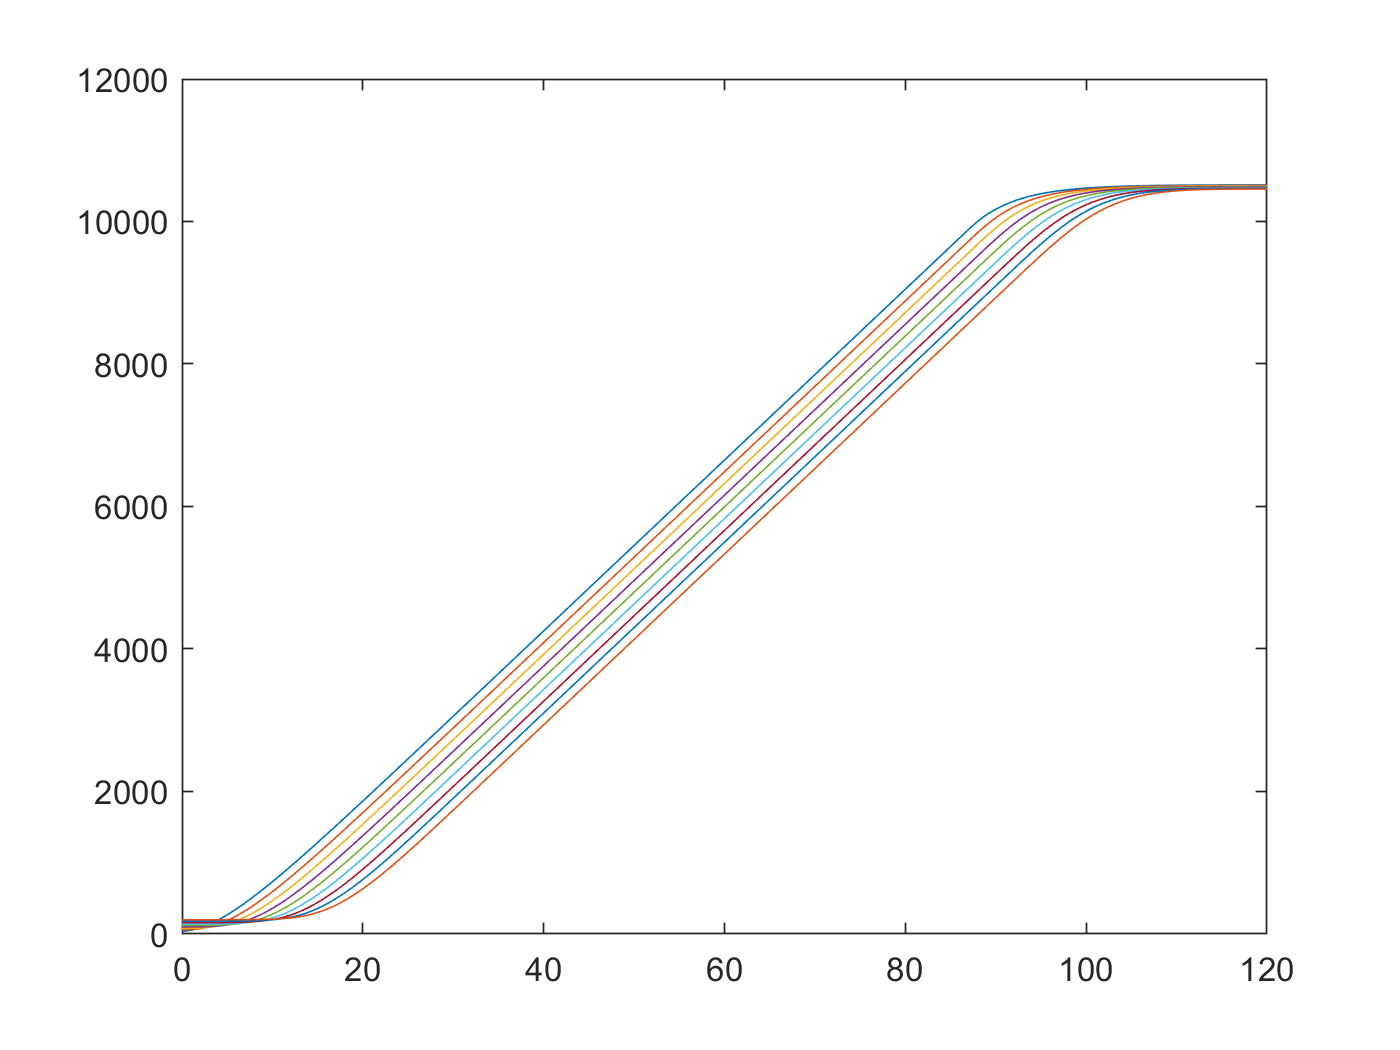

num_c = 9;
pos_0 = linspace(40, 200, num_c);
vel_0 = zeros(1,num_c);
acc_0 = ones(1,num_c);
gaps = ones(1,num_c)*20;
lengths = ones(1,num_c)*5;
tstep = 0.1;
t_final = 120;
gamma = 0.6;
numsteps = round(t_final/tstep);

for i = 1:num_c
    vehiclesInOrder(i) = Vehicle(pos_0(i), vel_0(i), acc_0(i), lengths(i));
end

tvals = linspace(0,t_final, numsteps);
xvals = zeros(numsteps, num_c);
vvals = zeros(numsteps, num_c);
avals = zeros(numsteps, num_c);

for t = 1:numsteps
    for i = 1:num_c
        
        % set leading vehicle velocity to speed limit of no cars in front
        if i == 1
            s = 10000 - vehiclesInOrder(1).state(1);
            v_l = vehiclesInOrder(1).state(2);
        else
            s = vehiclesInOrder(i-1).state(1) - vehiclesInOrder(i-1).width - vehiclesInOrder(i).state(1);
            v_l = vehiclesInOrder(i-1).state(2);
        end
        
        newstate = vehiclesInOrder(i).timestep(s, v_l, tstep, gamma);
        xvals(t, i) = newstate(1);
        vvals(t, i) = newstate(2);
        avals(t, i) = newstate(3);
      
    end
end

for i = 1:num_c
    plot(tvals, xvals(:,i))
    hold on;
end
hold off;

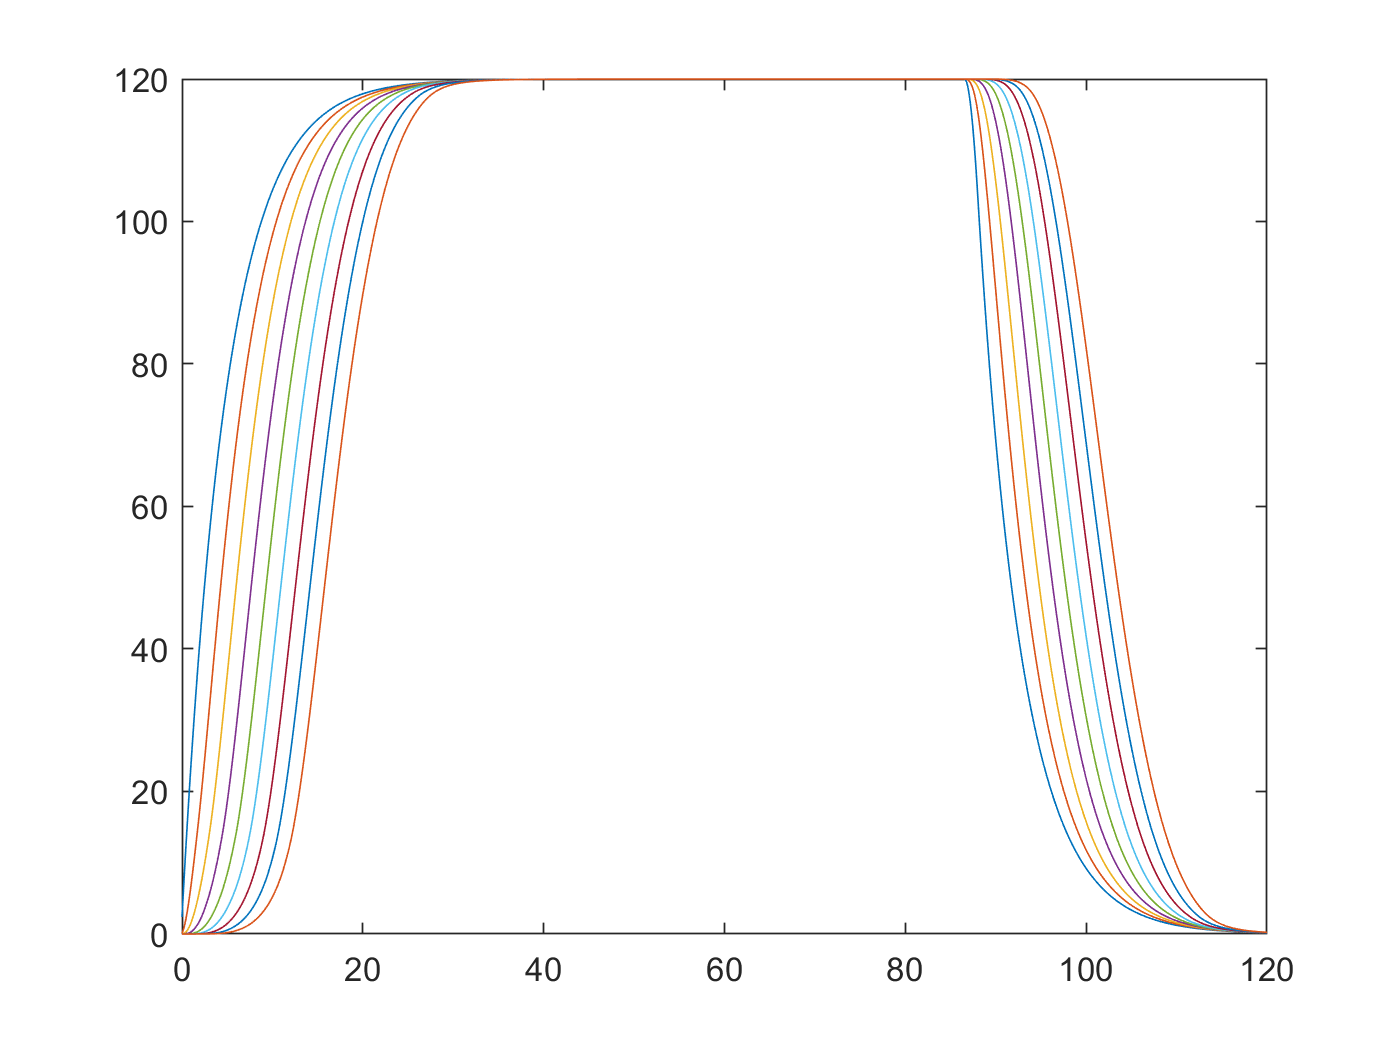

for i = 1:num_c
    plot(tvals, vvals(:,i))
    hold on;
end
hold off;

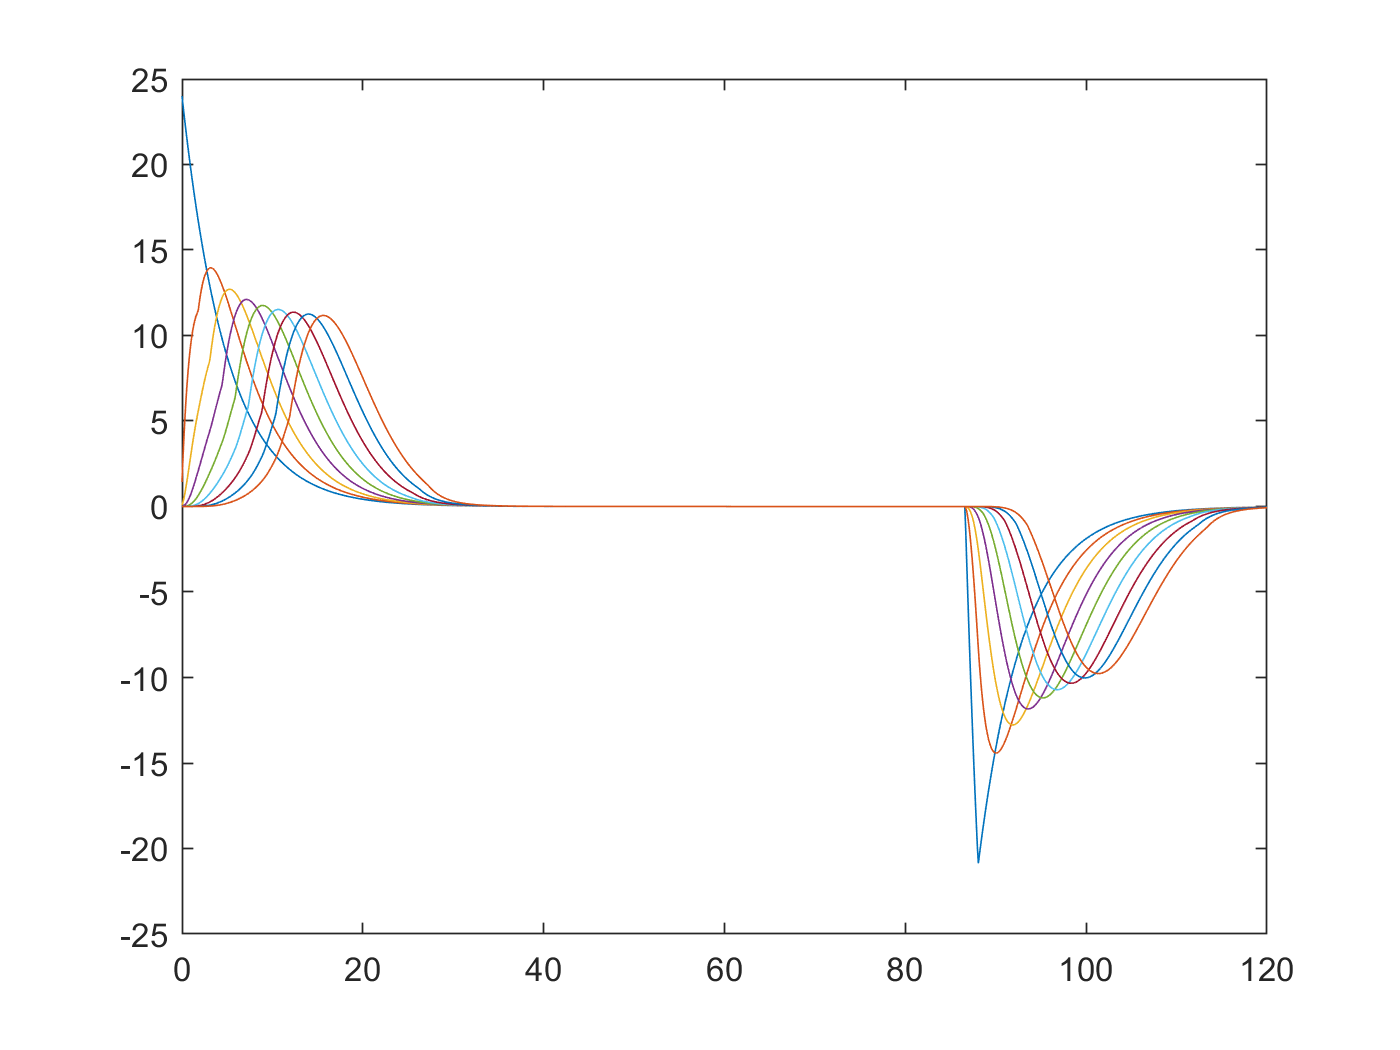

for i = 1:num_c
    plot(tvals, avals(:,i))
    hold on;
end
hold off;